.Align spikes to lap

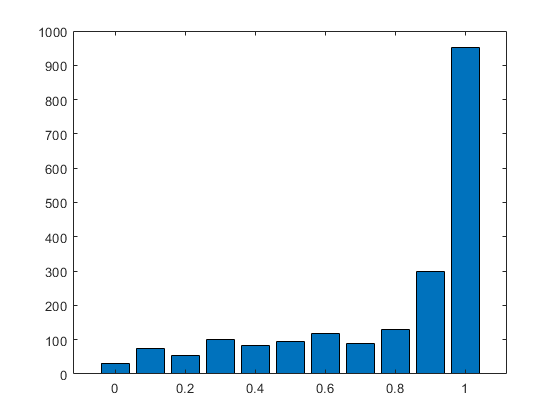

%% Hyperparameters setting
iscell=lap(1).iscell(:,2);
c=[0:0.1:1];

figure;
bar(c,hist(iscell,c));

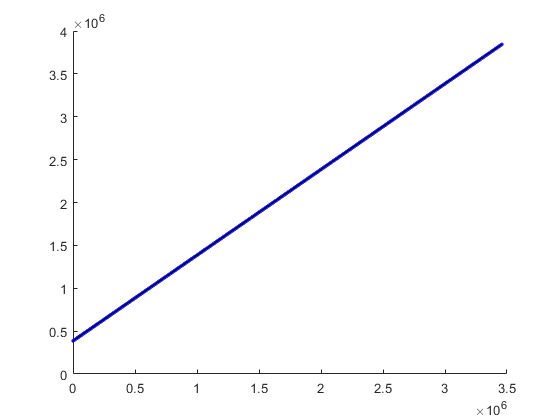


index_cell=find(iscell>=0.7);
num_cell=numel(index_cell);
num_lap=numel(lap);

cutoff_speed=2;

position_edge=0:2:239;% H5 239

% sigma=2;
% xk=[-3*sigma:3*sigma];
% kernel=exp(-xk.^2/2/sigma^2);
% kernel=kernel/sum(kernel);
% for i = 1:num_lap
%     lap(i).spk_smooth = filter(kernel,1,lap(i).spks,[],2);
% end

% transfer VR time into arduino time
t_unity=0;
t_arduino=0;

for i=1:num_lap
    t_sync=lap(i).t_sync;
    t_sync_arduino=lap(i).t_sync_arduino;
    num_t=numel(t_sync);
    t_unity((end+1):(end+num_t))=t_sync;
    t_arduino((end+1):(end+num_t))=t_sync_arduino;
end

t_unity(1)=[]; t_arduino(1)=[];
parameter=polyfit(t_unity,t_arduino,1);

figure; hold on;
plot(t_unity,t_arduino,'.b');
plot(t_unity,parameter(2)+parameter(1)*t_unity,'-k');


h = waitbar(0,'Align spk to position...');
for i=1:(num_lap-1)
    waitbar(i/num_lap,h);
    lap(i).t_position_arduino=round(parameter(2)+parameter(1)*lap(i).t_position);
    spk_interp=interp1(lap(i).t_sync_arduino_2p,lap(i).spks(index_cell,:)',lap(i).t_position_arduino','linear','extrap');
    speed_VR=diff(lap(i).position);
    index_nonzero=find(speed_VR>1e-3);
    index_start=index_nonzero(1);
    lap(i).spk_interp=spk_interp';
    lap(i).index_run=find((-lap(i).speed(index_start:end))>cutoff_speed)+index_start-1;
    lap(i).spk_interp_run=lap(i).spk_interp(:,lap(i).index_run);
    position_run=lap(i).position(lap(i).index_run);
    bins=discretize(position_run,position_edge);
    lap(i).spk_interp_position=zeros(num_cell,numel(position_edge)-1);
    for j=1:numel(position_edge)-1
        index_bin=find(bins==j);
         if ~isempty(index_bin)             
            lap(i).spk_interp_position(:,j)=mean(lap(i).spk_interp_run(:,index_bin),2);
         else
            lap(i).spk_interp_position(:,j)=mean([lap(i).spk_interp_run(:,find(bins==j-1 | bins==j+1))],2);
        end 
    end
end
delete(h);


% spk to zscore
for i =1:numel(lap)
    spk_interp_position = lap(i).spk_interp_position;
    spk_interp_position_zscore = zscore(spk_interp_position');
    lap(i).spk_interp_position_zscore = spk_interp_position_zscore';
end

Sort cells based on spikes

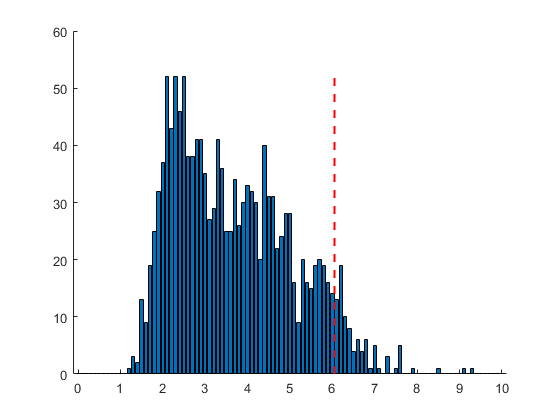

clear spk_neuron spk_neuron_type spk_type spk_type_norm peak_position median_response max_median_response;
clear spk_neuron_odd spk_neuron_even spk_odd spk_even spk_norm_odd spk_norm_even peak_position_odd peak_position_even;

index = find([lap.trial_class]==10); % 最后一位替换成空但不改变 reward 属性
if ~isempty(index)
    for i = 1:numel(index)
        lap(index(i)).trial_style(3) = 1;
    end
end

% trial_pool=[1,2,3;
%             1,3,2;
%             2,1,3;
%             2,3,1;
%             3,1,2;
%             3,2,1];
% trial_name=["XAB","XBA","AXB","ABX","BXA","BAX"];

trial_pool=[2,3,4;
            2,4,3;
            3,2,4;
            3,4,2;
            4,2,3;
            4,3,2];
trial_name=["ABC","ACB","BAC","BCA","CAB","CBA"];

% trial_pool=[2,3,4;
%             2,4,3;
%             3,2,4;
%             3,4,2;
%             4,2,3;
%             4,3,2;
%             6,3,7;
%             6,7,3;
%             3,6,7;
%             3,7,6;
%             7,6,3;
%             7,3,6];
% trial_name=["ABC","ACB","BAC","BCA","CAB","CBA","EBF","EFB","BEF","BFE","FEB","FBE"];



% trial_pool=[2,3,4;
%             2,4,3;
%             3,2,4;
%             3,4,2;
%             4,2,3;
%             4,3,2;
%             2,3,1;
%             2,4,1;
%             3,2,1;
%             3,4,1;
%             4,2,1;
%             4,3,1];
% trial_name=["ABC","ACB","BAC","BCA","CAB","CBA","ABX","ACX","BAX","BCX","CAX","CBX"];

% trial_pool=[2,3,5;
%             2,5,3;
%             3,2,5;
%             3,5,2;
%             5,2,3;
%             5,3,2];
% trial_name=["ABD","ADB","BAD","BDA","DAB","DBA"];

% trial_pool=[2,3,1;
%             3,2,1];
% trial_name=["ABX","BAX"];

% trial_pool=[1,2,3;
%             1,3,2;
%             2,1,3;
%             2,3,1;
%             3,1,2;
%             3,2,1;
%             2,3,5;
%             2,5,3;
%             3,2,5;
%             3,5,2;
%             5,2,3;
%             5,3,2];
% trial_name=["XAB","XBA","AXB","ABX","BXA","BAX","ABD","ADB","BAD","BDA","DAB","DBA"];
% 
% trial_pool=[2,3,4;
%             2,4,3;
%             3,2,4;
%             3,4,2;
%             4,2,3;
%             4,3,2;
%             2,3,5;
%             2,5,3;
%             3,2,5;
%             3,5,2;
%             5,2,3;
% %             5,3,2];
% trial_name=["ABC","ACB","BAC","BCA","CAB","CBA","ABD","ADB","BAD","BDA","DAB","DBA"];

% trial_pool=[1,2,3;
%             1,3,2;
%             2,1,3;
%             2,3,1;
%             3,1,2;
%             3,2,1;
%             2,3,4;
%             2,4,3;
%             3,2,4;
%             3,4,2;
%             4,2,3;
%             4,3,2];
% trial_name=["XAB","XBA","AXB","ABX","BXA","BAX","ABC","ACB","BAC","BCA","CAB","CBA"];


[n_type n_cue]=size(trial_pool);

h = waitbar(0,'Sort trial types...');
for i=1:num_cell
    waitbar(i/num_cell,h);
    num_trialtype=zeros(1,n_type);
    for j=1:(num_lap-1)
        spk_neuron(i).spk_position(j,:)=lap(j).spk_interp_position_zscore(i,:);
        for k=1:n_type
            if (lap(j).trial_style==trial_pool(k,:))
                num_trialtype(k)=num_trialtype(k)+1;
                spk_neuron_type(i,k).lap_position(num_trialtype(k),:)=lap(j).spk_interp_position_zscore(i,:);
                index_lap_type(k).index(num_trialtype(k))=j;
            end
        end
    end
    for k=1:n_type
        %peak_response=max(spk_neuron_type(i,k).spk_position');
        %median_response(i,k)=median(peak_response);
        
        %median_response(i,k,:)=median(spk_neuron_type(i,k).spk_position);
        median_response(i,k,:)=SelectPercentile(spk_neuron_type(i,k).lap_position,25);
        peak_response(i,k)=max(median_response(i,k,:));
    end
    max_median_spk(i)=max(peak_response(i,:));
end
delete(h);

h = waitbar(0,'Sort even/odd trials...');
for i=1:num_cell
    waitbar(i/num_lap,h);
    for k=1:n_type
        spk_neuron_odd(i,k).spk_position=spk_neuron_type(i,k).lap_position(1:2:end,:);
        spk_neuron_even(i,k).spk_position=spk_neuron_type(i,k).lap_position(2:2:end,:);
    end
end
delete(h);

c=[0:0.1:10];
cutoff_spk=6;

hist_peak=hist(max_median_spk,c);

figure;hold on;
bar(c,hist_peak);
plot([cutoff_spk+0.05,cutoff_spk+0.05],[0,max(hist_peak)],'--r','LineWidth',1.5);


h = waitbar(0,'Sort responsive neurons...');
index_responsive=find(max_median_spk>cutoff_spk);

for k=1:n_type
    waitbar(k/n_type,h);
    for i=1:numel(index_responsive)
        spk_type(k,i,:)=mean(spk_neuron_type(index_responsive(i),k).lap_position);
        spk_type_norm(k,i,:)=spk_type(k,i,:)/max(spk_type(k,i,:));
        peak_position(k,i)=find(spk_type(k,i,:)==max(spk_type(k,i,:)),1);
        
        spk_odd(k,i,:)=mean(spk_neuron_odd(index_responsive(i),k).spk_position);
        spk_norm_odd(k,i,:)=spk_odd(k,i,:)/max(spk_odd(k,i,:));
        peak_position_odd(k,i)=find(spk_odd(k,i,:)==max(spk_odd(k,i,:)),1);
        
        spk_even(k,i,:)=mean(spk_neuron_even(index_responsive(i),k).spk_position);
        spk_norm_even(k,i,:)=spk_even(k,i,:)/max(spk_even(k,i,:));
        peak_position_even(k,i)=find(spk_even(k,i,:)==max(spk_even(k,i,:)),1);
        
    end
end
delete(h);

提取cell_pos_trial 三维数组

spk_neuron_type_responsive = spk_neuron_type(index_responsive, :);

function y_percentile=SelectPercentile(y,percentile)

% percentile - [0,100]; pick the number in each COLUMN at the defined percentile (from the largest value)

[m n]=size(y);
for i=1:n
    x=y(:,i);
    x_sort=sort(x,'descend');
    y_percentile(i)=x_sort(round(m*percentile/100));
end
end